close all;
clear;
clc;

load dataOut/testData5.mat

x1 = testData.x1;
x2 = testData.x2;
x3 = testData.x3;

dx1 = testData.dx1;
dx2 = testData.dx2;
dx3 = testData.dx3;

n = 3;
m = 3;
u1 = testData.u1;

% plot(xD(:,1),dxD(:,1))
% plot(xD(:,2),dxD(:,1))
% plot(xD(:,3),dxD(:,1))

% dx13 = xD(:,1) - xD(:,3); 
% dx32 = xD(:,3) - xD(:,2); 
% %dx13 = xD(:,1) - xD(:,3);
% 
% plot(dx13, dxD(:,1));
% hold on;
% plot(dx13, dxD(:,3));

% load data/threeTankParameter1.mat
% sigmaX = [1e-9, 0, 0; 0, 1e-9, 0; 0, 0, 1e-9];
% sigmaY = [1e-7, 0, 0; 0, 1e-7, 0; 0, 0, 1e-7];
% threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);
% x = zeros(400,3);
% time = zeros(400,1);
% xK = [0,0,0];
% 
% u(1:180) = parameter.u1;
% %u(6:180) = parameter.u1;
% % parameter.u1 = 0;
% % u(1:5) = parameter.u1;
% % threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);
% % for i = 1 : 5
% %     time(i) = i;
% %     xK = threeTank.stateTransition(xK,1);
% %     yK = threeTank.measurement(xK);
% %     x(i,:) = yK;
% %     
% % end
% % parameter.u1 = u(6)
% threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);
% %for i = 6 : 180
% for i = 1 : 180
%     time(i) = i;
%     xK = threeTank.stateTransition(xK,1);
%     yK = threeTank.measurement(xK);
%     x(i,:) = yK;
%     
% end
% parameter.u1 = 0;
% u(181:399) = parameter.u1;
% threeTank = WaterTank(3,3,sigmaX,sigmaY,parameter);
% for i = 181 : 400
%     time(i) = i;
%     xK = threeTank.stateTransition(xK,1);
%     yK = threeTank.measurement(xK);
%     x(i,:) = yK;
%     
% end
% x1 = smoothdata(x(:,1),'gaussian',5);
% x2 = smoothdata(x(:,2),'gaussian',5);
% x3 = smoothdata(x(:,3),'gaussian',5);
% % x1 = x(:,1);
% % x2 = x(:,2);
% % x3 = x(:,3);
% 
% plot(time,x1);
% hold  on;
% plot(time,x(:,1));
% plot(time,x2);
% plot(time,x3);
% hold off;
% for i = 2 : 400
% %     dx1(i-1) = smoothdata(x1(i)-x1(i-1),'gaussian');
% %     dx2(i-1) = smoothdata(x2(i)-x2(i-1),'gaussian');
% %     dx3(i-1) = smoothdata(x3(i)-x3(i-1),'gaussian');
%     dx1(i-1) = x1(i)-x1(i-1);
%     dx2(i-1) = x2(i)-x2(i-1);
%     dx3(i-1) = x3(i)-x3(i-1);
% end
% 
% x1 = x1(1:399,:);
% x2 = x2(1:399,:);
% x3 = x3(1:399,:);
% plot (dx1)
% hold on;
% plot (dx2)
% plot (dx3)
% hold off;



dx13 = x1 - x3; 
dx32 = x3 - x2;


Checkout x3

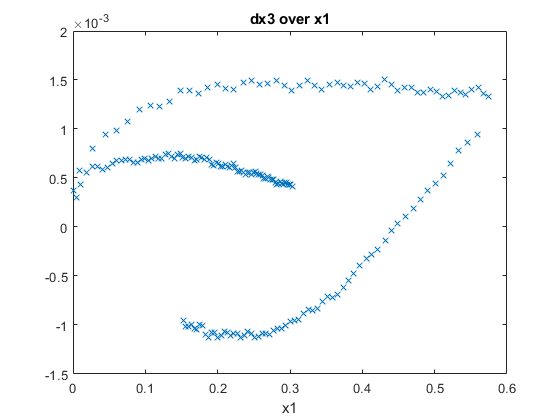

plot(x1,dx3,"x")
xlabel("x1")
title("dx3 over x1")

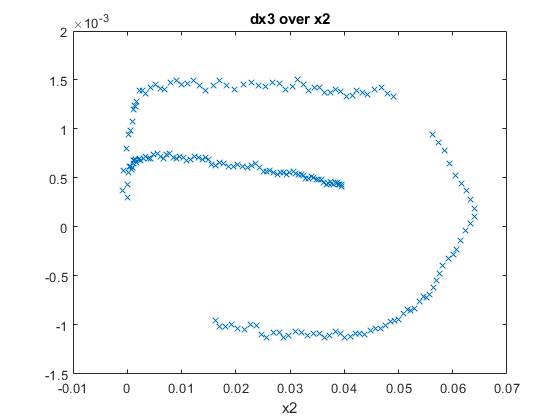

plot(x2,dx3,"x")
xlabel("x2")
title("dx3 over x2")

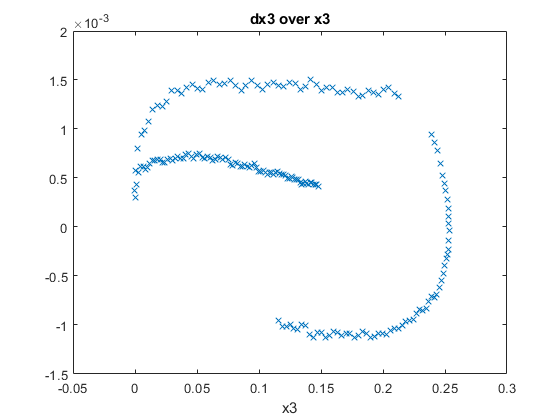

plot(x3,dx3,"x")
xlabel("x3")
title("dx3 over x3")

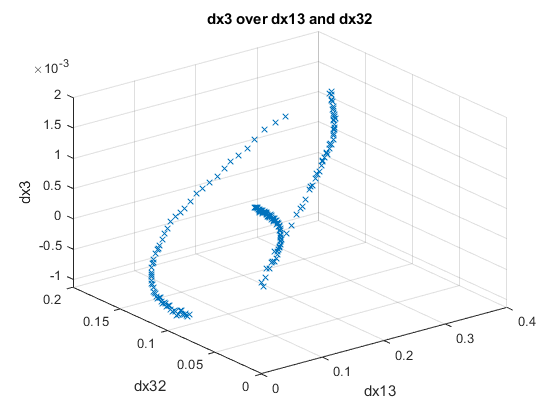



plot3(dx13,dx32,dx3,'x')
xlabel("dx13")
ylabel("dx32")
zlabel("dx3")
title("dx3 over dx13 and dx32")
grid on;

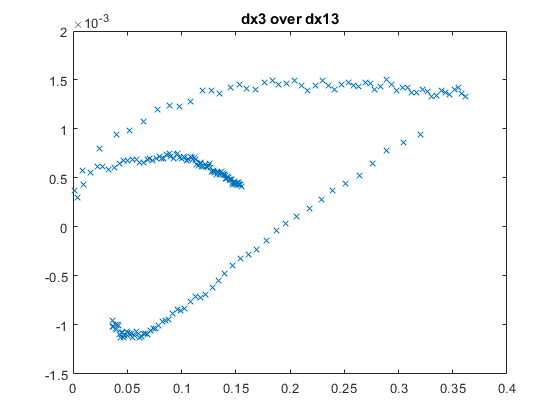


plot(dx13,dx3,"x")
title("dx3 over dx13")

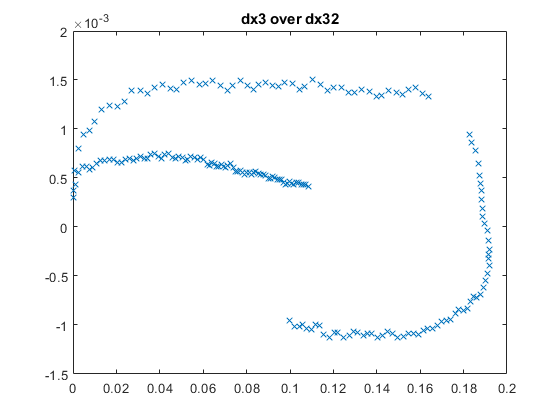


plot(dx32,dx3,"x")
title("dx3 over dx32")

Checkout x1

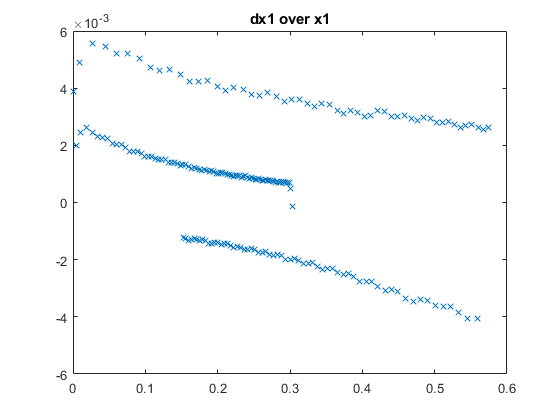

plot(x1,dx1,"x")
title("dx1 over x1")

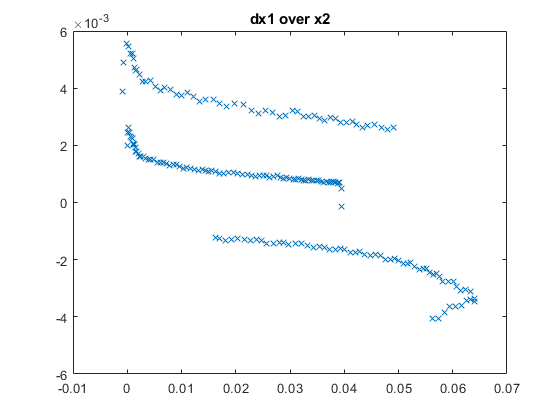

plot(x2,dx1,"x")
title("dx1 over x2")

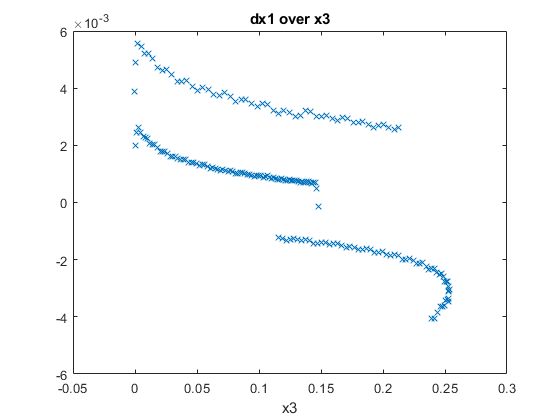

plot(x3,dx1,"x")
xlabel("x3")
title("dx1 over x3")

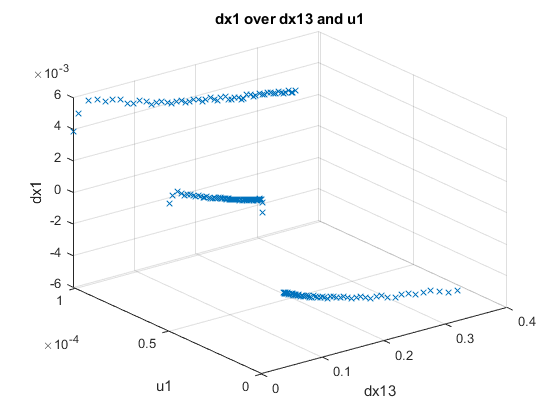



plot3(dx13,u1,dx1,'x')
xlabel("dx13")
ylabel("u1")
zlabel("dx1")
title("dx1 over dx13 and u1")
grid on;


% plot(dx13,dx3,"x")
% title("dx3 over dx13")
% 
% plot(dx32,dx3,"x")
% title("dx3 over dx32")

Checkout x2

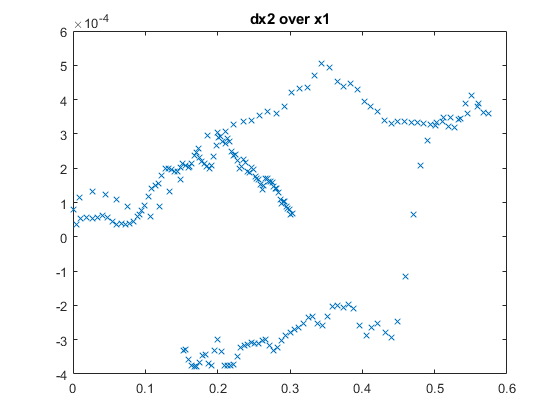

plot(x1,dx2,"x")
title("dx2 over x1")

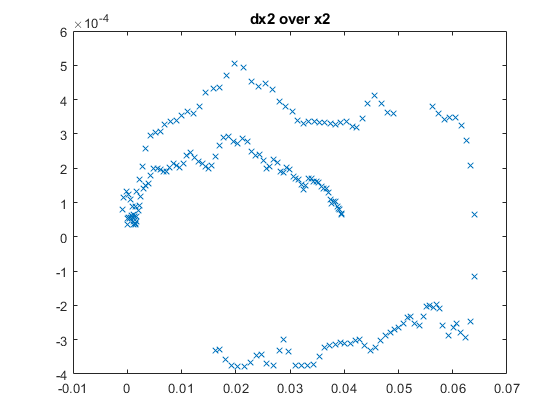

plot(x2,dx2,"x")
title("dx2 over x2")

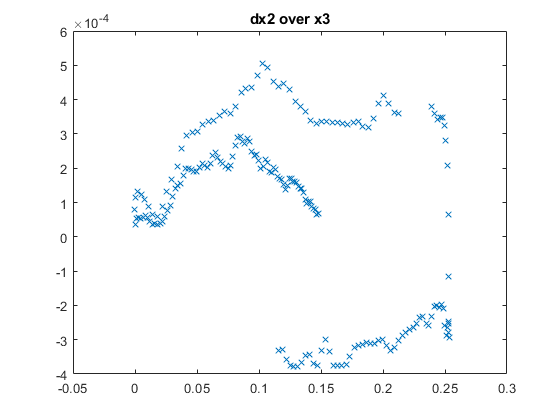

plot(x3,dx2,"x")
title("dx2 over x3")

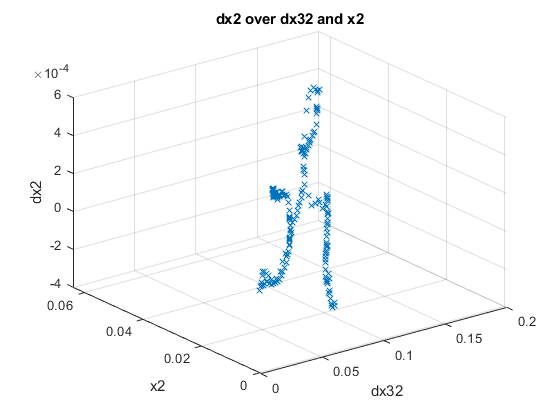



plot3(dx32,x2,dx2,'x')
xlabel("dx32")
ylabel("x2")
zlabel("dx2")
title("dx2 over dx32 and x2")
grid on;


% plot(dx13,dx3,"x")
% title("dx3 over dx13")
% 
% plot(dx32,dx3,"x")
% title("dx3 over dx32")


% plot(dx13,dx1,"x")
% 
% dx2R = x2;
% 
% 
% [a,b] = meshgrid(dx13,dx32);
% % a =a.';
% % b = b.';
% % %c = logLike(:,:,v);
% %contour(a,b,dx3,'ShowText','on')
% 
% 
% plot3(dx32,dx2R,dx2,'x')
% grid on;
% plot3(u,dx13,dx1,'x')
% grid on;

% plot3(x1,x3,dx1,'x');
% plot3(x3,x2,dx1,'x');

% y1 = x1;
% y2 = x2;
% y3 = x3;
% dx1 = dx1.';
% dx2 = dx2.';
% dx3 = dx3.';
% u = u.';
% 
% time = time(1:399);
% testData = table(time,x1,x2,x3,dx1,dx2,dx3,y1,y2,y3,u,dx13,dx32,dx2R);
% save("dataOut/testData4.mat","testData");